# Fin Flutter Analysis

clear all

## **Variables**

#### **Geometry:**

Root Chord:

Cr = 13; %inches
Crm = Cr*25.4;%mm

Tip Chord:

Ct = 1; %inches
Ctm = Ct*25.4; %mm

Semi-Span: (height from body tube to tip)

b = 3.4; %inches
bm = b*25.4; %mm

#### Material/Vehicle Properties:

Shear Modulus:

G = 600000;%2700000; %psi
Gm = G*6.8947572931e-6; %GPa

Thickness:

t = 0.28; %inches
tm = t*25.4; %mm

Elevation:

h = 0:50:30000; %ft
hm = h/3.281; %m

Ambient Temperature

T = 290; %Kelvin

## Calculations

S = 0.5*(Crm+Ctm)*bm;
lambda = Ctm/Crm;
g = 9.81; %m/s^2 
M = 0.02896; % kg/mol for air
R = 8.314; %(kg*m^2)/(s^2*K*mol)
H = 8077%(R*T)/(M*g); %m scale height

H =         8077


Cso = sqrt(1.4*T*287.7); %m/s speed of sound at sea level 
Po = .000101325; %GPa pressure at sea level 
B = bm^2/S; %aspect ratio 
NT = tm/Crm; %mm/mm normalized thickness
Vf = 1.223*Cso*exp(0.4*hm/H)*sqrt(Gm/Po)*sqrt((2+B)/1+lambda)*(NT/B)^(3/2)

Vf =        1262.5       1263.5       1264.4       1265.4       1266.3       1267.3       1268.2       1269.2       1270.1       1271.1       1272.1         1273         1274       1274.9       1275.9       1276.9       1277.8       1278.8       1279.8       1280.7       1281.7       1282.7       1283.6       1284.6       1285.6       1286.5       1287.5       1288.5       1289.5       1290.4       1291.4       1292.4       1293.4       1294.3       1295.3       1296.3       1297.3       1298.2       1299.2       1300.2       1301.2       1302.2       1303.2       1304.1       1305.1       1306.1       1307.1       1308.1       1309.1       1310.1


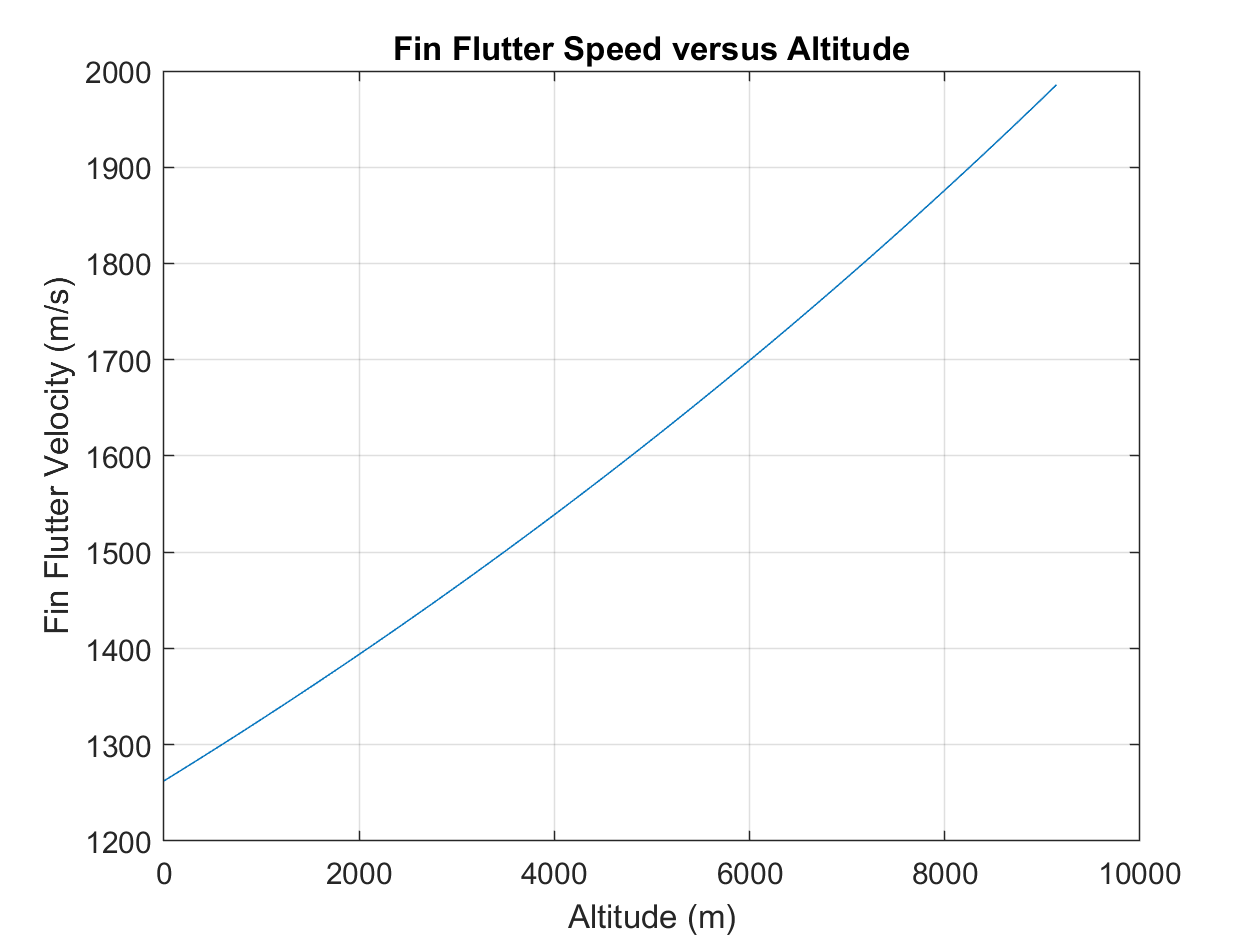

plot(hm,Vf)
ylabel 'Fin Flutter Velocity (m/s)'
xlabel 'Altitude (m)'
title 'Fin Flutter Speed versus Altitude'
grid on

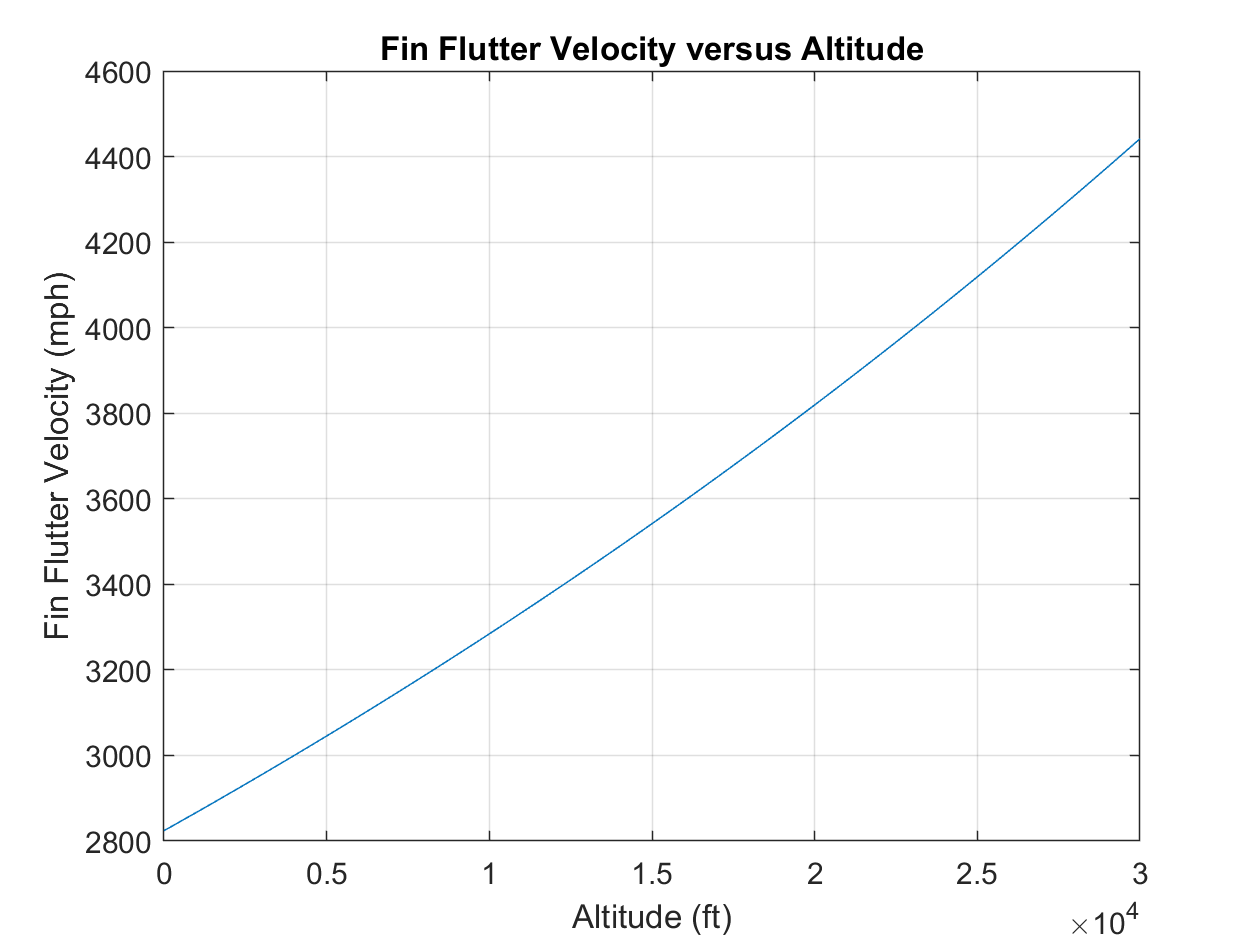

plot(hm*3.28084,Vf*2.23694)
% xlim([0 10000])
xlabel 'Altitude (ft)'
ylabel 'Fin Flutter Velocity (mph)'
grid on
title 'Fin Flutter Velocity versus Altitude'

### Find Final Fin Flutter Velocity (change h == (apogee))

height = find(h == 4650); %index of height in feet. Change number to height of max velocity, not apogee. 
Vf(height) %m/s

ans =        1354.3


Vf(height)*2.23694 %mph

ans =        3029.5
